## Experiment / Analysis

### Experimental Setup

function images = loadShapesFromFolder(folderPath)
    imgs = dir(fullfile(folderPath, '**', '*.jpg')); 
    % n = numel(imgs);
    n = 50
    images = cell(n,1);

    for i = 1:n
        I = imread(fullfile(imgs(i).folder, imgs(i).name));
        % Convert to grayscale
        if ismatrix(I)
            I = im2gray(I);
        else
            I = rgb2gray(I);
        end
        % I = imbinarize(I);  % ensure binary
        images{i} = I;
    end
    disp(['Loaded ', num2str(n), ' images from ', folderPath]);
end
function contour = findBWContour(I)
    % findBWContour - Detects and plots the largest external contour in a
    % binary or grayscale image. This is much simpler than the demo contour
    % extraction method as bwboundaries is built to handle these silhoutte
    % images as opposed to the images used in the demo which had more
    % complex contours than the ones seen in this dataset.
    
    % Inputs:
    %   I - Grayscale or binary image. Foreground should be white, background black
    %
    % Outputs:
    %   contour - Nx2 array of [x, y] coordinates representing the largest external contour.
    %

    % Make sure the image is binary
    BW = imbinarize(I);
    % Detect borders of binary image
    [B,L] = bwboundaries(BW,'noholes');

    % Select the largest/outermost contour detected
    [~, idx] = max(cellfun(@length, B));
    contour = B{idx};

end

function C_interp = groundTruthInterpolate(C1, C2, alpha, numPoints)
    % interpolateContours - Linear interpolation between two contours. 
    %
    % Input:
    %   C1, C2    - Nx2 and Mx2 arrays of [row, col] points
    %   alpha     - interpolation factor (0 = C1, 1 = C2)
    %   numPoints - number of points to resample for interpolation (optional, default 100)
    %
    % Output:
    %   C_interp  - Nx2 interpolated contour

    % Resample both contours to have numPoints points
    t1 = linspace(1, size(C1,1), numPoints);
    t2 = linspace(1, size(C2,1), numPoints);

    C1_resampled = [interp1(1:size(C1,1), C1(:,1), t1)', interp1(1:size(C1,1), C1(:,2), t1)'];
    C2_resampled = [interp1(1:size(C2,1), C2(:,1), t2)', interp1(1:size(C2,1), C2(:,2), t2)'];

    % Linear interpolation
    C_interp = (1-alpha)*C1_resampled + alpha*C2_resampled;
end

function z_resampled = preprocess(contour, N)
    % preprocess - process the contours to get consistency amongst the
    % contours, making them interpolatable.
    %
    % Inputs:
    %   contour - [row, col] coordinate list (y, x)
    %   N - number of points you want in the Fourier representation
    % 
    % Outpus:
    %   z_resampled - a complex-valued 1×N vector representing the contour

    % Extract x, y and create z
    x = contour(:,2);   % column = x
    y = contour(:,1);   % row = y
    z = x + 1i*y;

    % Ensure counterclockwise orientation
    if ispolycw(x, y)
        z = flip(z);
    end

    % Anchor the shape
    % Move the Left-most point to the start
    [~, idx_min] = min(real(z));   % smallest x
    z = circshift(z, -idx_min + 1);

    % Arc-length parameterization – better than uniform indexing because contour
    % points aren't evenly spaced. Using true distance along the curve gives a
    % smoother, more consistent sampling for the Fourier descriptors.
    d = abs(diff(z));             % distances between samples
    s = [0; cumsum(d)];           % cumulative arc length
    s = s / s(end);               % normalize to [0,1]

    % Resample at N equally spaced arc-length points
    s_new = linspace(0, 1, N);
    z_resampled = interp1(s, z, s_new, 'linear');

    % Translation normalization
    z_resampled = z_resampled - mean(z_resampled);

    % Scale normalization
    z_resampled = z_resampled / max(abs(z_resampled));


    % Re-anchor leftmost point -
    % This stabilizes orientation 
    [~, idx_min] = min(real(z_resampled));
    z_resampled = circshift(z_resampled, -idx_min + 1);
end

function [x,y] = scaleToImage(z, imgSize)
    % scaleToImage - aps a normalized complex contour into pixel coordinates
    %
    % Inputs:
    %   z - complex valued contour representation
    %   imgSize - size of output image
    % 
    % Outpus:
    %   [x, y] - x and y coordinates of the scaled contour

    % Get x and y coordinates
    x = real(z);
    y = imag(z);

    % Scale to fit inside the image 
    minX = min(x);  maxX = max(x);
    minY = min(y);  maxY = max(y);

    width  = maxX - minX;
    height = maxY - minY;

    % Compute scale factor to fit within image ( no margins for experiment)
    s = 1.0 * min(imgSize(2) / width, imgSize(1) / height); % 1.0 = margin

    x = (x - minX) * s;
    y = (y - minY) * s;

    % Now center inside the image
    X_center = (imgSize(2) - max(x)) / 2;
    Y_center = (imgSize(1) - max(y)) / 2;

    x = x + X_center;
    y = y + Y_center;

end


### Run Experiment

% Driver Code

shapes = loadShapesFromFolder('original');

n = 50

Loaded 50 images from original


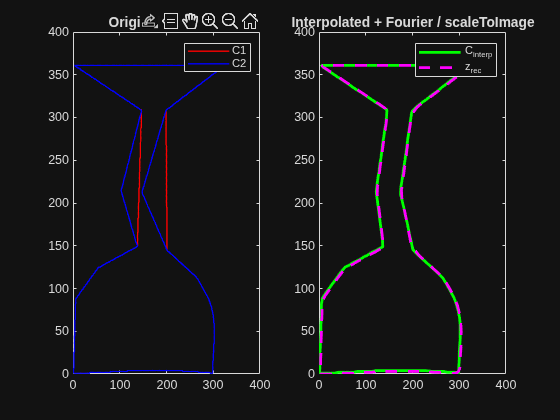

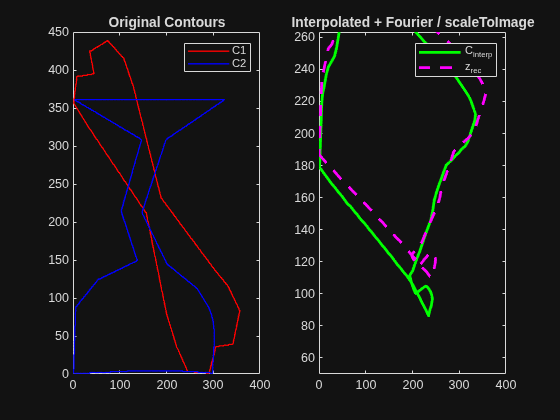

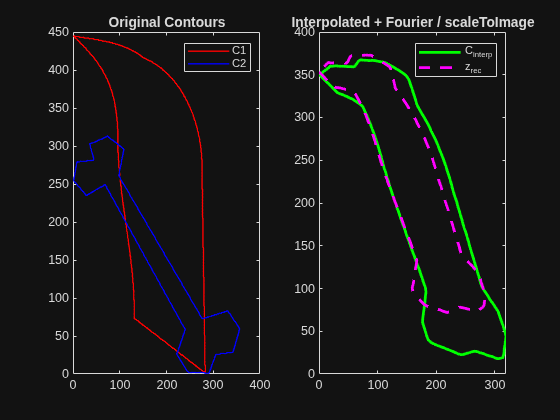


numShapes = numel(shapes);  % total number of images

% Number of pairs you want to sample
numPairs = 1000;
numPoints = 100;
alpha = 0.5;
GT_interpolations = cell(numPairs,1);
Fourier_interpolations = cell(numPairs,1);
metricsArray = cell(numPairs,1); 


% Preallocate cell arrays to store contours
contourPairs = cell(numPairs, 2);

for k = 1:numPairs
    % Randomly pick two different indices
    idx = randperm(numShapes, 2);
    pairIndices(k,:) = idx;  % save the images (for plotting)

    I1 = shapes{idx(1)};
    I2 = shapes{idx(2)};

    % Ensure grayscale
    if ~ismatrix(I1), I1 = rgb2gray(I1); else, I1 = im2gray(I1); end
    if ~ismatrix(I2), I2 = rgb2gray(I2); else, I2 = im2gray(I2); end

    % Extract contours using your function
    contourPairs{k,1} = findBWContour(I1);
    contourPairs{k,2} = findBWContour(I2);

    C1 = contourPairs{k,1};
    C2 = contourPairs{k,2};

    % Interpolate directly on contours for ground truth
    C_interp = groundTruthInterpolate(C1, C2, alpha, 200);
    GT_interpolations{k} = C_interp; % store for evaluation

    % ---- Experimental Part ----
    % Preprocess contours, converting them into complex valued
    % representations needed for Fourier Transform and orienting them
    % in a consistent way
    z1 = preprocess(C1, 200);
    z2 = preprocess(C2, 200);

    % Apply Fourier Transform
    Z1 = fft(z1);
    Z2 = fft(z2);


    % Interpolate on Fourier Transforms
    Z_blend = (1 - alpha) * Z1 + alpha * Z2;
    z_rec = ifft(Z_blend); % Reconstruct
    
    % Assume image size and normalize
    imgSize = [size(I1,1), size(I1,2)];  % [height, width] of original image
    z = z_rec - mean(z_rec);          % center around 0
    scaleFactor = 0.5 * min(imgSize); % scale to fit the image
    z = z * scaleFactor;

    % Refit the complex contours into plotable x, y coordinates
    [x, y] = scaleToImage(z, imgSize);
    Fourier_interpolations{k} = [y(:), x(:)]; % store for evaluation
    
    if k < 5
        figure;

        % Subplot 1: Original contours + interpolation
        subplot(1,2,1);  % 1 row, 2 columns, first plot
        plot(C1(:,2), C1(:,1), 'r', 'LineWidth', 1); hold on;
        plot(C2(:,2), C2(:,1), 'b', 'LineWidth', 1);
        title('Original Contours');
        legend('C1','C2');
    
        % Subplot 2: Fourier / scaleToImage reconstruction
        subplot(1,2,2);  % second plot
        plot(C_interp(:,2), C_interp(:,1), 'g', 'LineWidth', 2); hold on;
        plot(x, y, 'm--', 'LineWidth', 2);
        % axis equal; set(gca,'YDir','reverse');
        title('Interpolated + Fourier / scaleToImage');
        legend('C_{interp}','z_{rec}');
    end
end

### Contour Plots

% Display first pair's contours (Wanted to show this in final report)
figure;
subplot(1,2,1); 
imshow(shapes{pairIndices(1,1)}); hold on;
plot(contourPairs{1,1}(:,2), contourPairs{1,1}(:,1), 'r', 'LineWidth', 2);
title('Contour 1');

subplot(1,2,2); 
imshow(shapes{pairIndices(1,2)}); hold on;
plot(contourPairs{1,2}(:,2), contourPairs{1,2}(:,1), 'r', 'LineWidth', 2);
title('Contour 2');

### Evaluation

function metrics = evaluate(C_interp, C_gt)
    % Evaluate similarity between Fourier interpolation and ground truth contour
    %
    % Inputs:
    %   C_interp : Nx2 interpolated contour from Fourier descriptors
    %   C_gt     : Nx2 ground truth interpolated contour
    %
    % Output:
    %   metrics : struct with mse, meanDist, rmse

    % Ensure both contours have same number of points
    if size(C_interp,1) ~= size(C_gt,1)
        error('Contours must have the same number of points for comparison.');
    end

    % Euclidean distance between each corresponding point
    diff = C_interp - C_gt;
    dists = sqrt(sum(diff.^2, 2));

    % Metrics
    mse  = mean(sum(diff.^2, 2));     % MSE across both x & y
    rmse = sqrt(mse);
    meanDist = mean(dists);

    % Package results
    metrics = struct( ...
        'mse', mse, ...
        'rmse', rmse, ...
        'meanDist', meanDist, ...
        'distances', dists ...
    );
end

% Gather evaluation metrics
% Initialize metrics to 0's for every pair of images (contours)
allMSE  = zeros(numPairs,1);
allMean = zeros(numPairs,1);
allRMSE = zeros(numPairs,1);
allMax  = zeros(numPairs,1);

% For each pair, gather evaluation metrics
for k = 1:numPairs
    C_gt = GT_interpolations{k};
    C_fourier = Fourier_interpolations{k};

    metrics = evaluate(C_fourier, C_gt);
    metricsArray{k} = metrics;

    allMSE(k)  = metrics.mse;
    allMean(k) = metrics.meanDist;
    allRMSE(k) = metrics.rmse;
end

% Print Summary
fprintf("Average MSE:  %.4f\n", mean(allMSE));

Average MSE:  657.0121


fprintf("Average RMSE: %.4f\n", mean(allRMSE));

Average RMSE: 22.6642


fprintf("Average Mean Dist: %.4f\n", mean(allMean));

Average Mean Dist: 21.3688


figure;
boxplot([allMSE allRMSE allMean allMax], ...
    'Labels', {'MSE','RMSE','MeanDist','MaxDist'});
title('Error Distribution Across All Interpolations');
grid on;

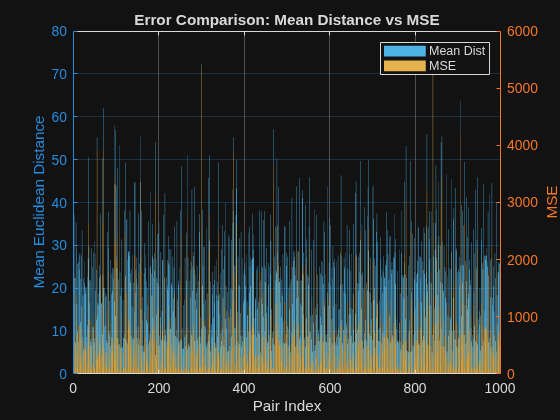


figure;
yyaxis left
bar(allMean, 'FaceColor', [0.3 0.7 0.9]);
ylabel('Mean Euclidean Distance');

yyaxis right
bar(allMSE, 'FaceColor', [0.9 0.7 0.3]);
ylabel('MSE');

xlabel('Pair Index');
title('Error Comparison: Mean Distance vs MSE');
grid on;
legend('Mean Dist','MSE');